clear 
clc

steerAng = 35;
fs = 41.667e3;
sweepDur = 10;
silenceDur = 2;
tone = sweeptone(sweepDur,silenceDur,fs, 'SweepFrequencyRange', [20 20.8e3]);
%toneNoSilence = tone(1:end-round(silenceDur*fs)-1)
tone = [zeros(silenceDur*fs-1,1); tone];

tone =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


t = 0:1/fs:sweepDur+(silenceDur-1/fs)*2;

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012


%plot(t, tone)

maxDegs = 9;
outputPower = zeros(maxDegs+1,4096);
outputFreq = zeros(maxDegs+1,4096);

for d = 0:maxDegs
    %fileID = fopen('degree_5');
    fileID = fopen('degree_' + string(d));
    data = fread(fileID,'single'); 
    %data = data/max(data)*2; 
    data = data/(power(2,31)-1);
    numMics = 8;
    numSamples = 190;
    onePacketLength = numSamples*numMics;
    numPacketsInData = floor(length(data)/onePacketLength);
    splitdata = zeros(numSamples,numMics);
    for i = 0:numPacketsInData-1
    splitdata = [splitdata; reshape(data(i*onePacketLength+1:(i+1)*onePacketLength),[],numMics)];
    end
    splitdata = splitdata(numSamples+1:end,:)';
    
    impulse = impzest(tone, splitdata(8,:)');
    impulse = impulse / max(abs(impulse));
    
    [p, f] = pspectrum(impulse,fs);

    outputPower(d+1,:)  = p;
    outputFreq(d+1,:)   = f;
end
outputdB = 10*log10(outputPower)

outputdB =   -47.4122  -47.5698  -48.0254  -48.7149  -49.4865  -50.0567  -50.0854  -49.4487  -48.3567  -47.1063  -45.8857  -44.7762  -43.8045  -42.9751  -42.2835  -41.7197  -41.2692  -40.9146  -40.6381  -40.4245  -40.2633  -40.1485  -40.0765  -40.0439  -40.0459  -40.0760  -40.1268  -40.1912  -40.2630  -40.3374  -40.4109  -40.4823  -40.5518  -40.6214  -40.6936  -40.7713  -40.8565  -40.9504  -41.0523  -41.1600  -41.2691  -41.3733  -41.4653  -41.5377  -41.5843  -41.6018  -41.5913  -41.5583  -41.5115  -41.4611
  -71.0545  -71.1091  -71.1947  -71.0837  -70.4972  -69.3472  -67.8287  -66.2102  -64.6635  -63.2589  -62.0113  -60.9141  -59.9562  -59.1274  -58.4187  -57.8198  -57.3184  -56.8998  -56.5499  -56.2571  -56.0144  -55.8185  -55.6680  -55.5607  -55.4926  -55.4579  -55.4499  -55.4618  -55.4880  -55.5240  -55.5668  -55.6146  -55.6669  -55.7245  -55.7886  -55.8604  -55.9409  -56.0300  -56.1265  -56.2274  -56.3288  -56.4254  -56.5115  -56.5815  -56.6310  -56.6572  -56.6608  -56.6452  -56.61

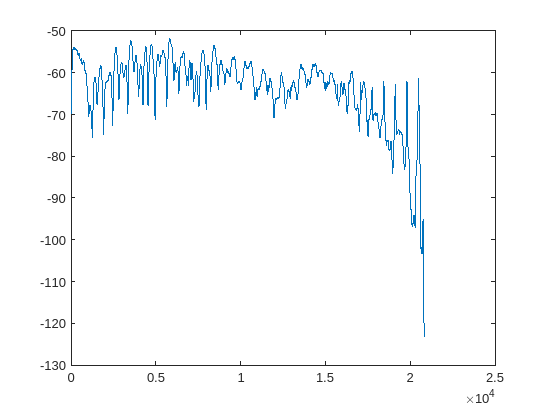

outputdB = outputdB - max(10*log10(outputPower));
plot(outputFreq(3,:), 10*log10(outputPower(3,:)))

circPlot(outputFreq(20), (0:maxDegs)*pi/180, outputdB', steerAng)

circPlot is not found in the current folder or on the MATLAB path, but exists in:
    /home/jonas/gitten/ES10-Drowning
    /home/jonas/SLDMAScripts

Change the MATLAB current folder or add its folder to the MATLAB path.

cylindricalPlot(outputFreq(1,:), (0:maxDegs)*pi/180, outputdB', steerAng, [180, 10])